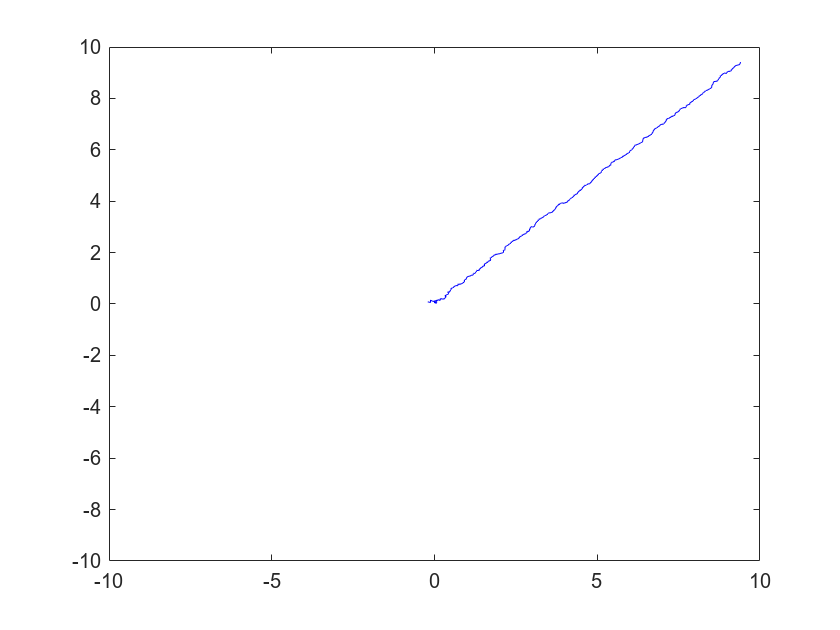

% Dati di misura del sensore 1
z1 = [x1_meas; y1_meas]; % posizione misurata dal sensore 1

R1 = [sigma_x1^2, 0; 0, sigma_y1^2]; % matrice di covarianza del sensore 1

% Dati di misura del sensore 2
z2 = [x2_meas; y2_meas]; % posizione misurata dal sensore 2
R2 = [sigma_x2^2, 0; 0, sigma_y2^2]; % matrice di covarianza del sensore 2

% Inizializzazione delle variabili del filtro di Kalman
state = [0; 0; 0; 0]; % stato iniziale [x; y; vx; vy]
P = eye(4); % matrice di covarianza iniziale
Q = eye(4) * 0.01; % rumore di processo

% Matrici di osservazione per i due sensori
H1 = [1 0 0 0; 0 1 0 0]; % matrice di osservazione per il sensore 1
H2 = [1 0 0 0; 0 1 0 0]; % matrice di osservazione per il sensore 2

% Filtro di Kalman: Aggiornamento con il sensore 1
K1 = P * H1' / (H1 * P * H1' + R1);
state1 = state + K1 * (z1 - H1 * state);
P1 = (eye(4) - K1 * H1) * P;

% Filtro di Kalman: Aggiornamento con il sensore 2
K2 = P * H2' / (H2 * P * H2' + R2);
state2 = state + K2 * (z2 - H2 * state);
P2 = (eye(4) - K2 * H2) * P;

% Stato stimato fuso
state_fused = (state1 + state2) / 2; % Media dei due stati stimati
P_fused = (P1 + P2) / 2; % Media delle due matrici di covarianza

% Stato stimato
x_est = state_fused(1);
y_est = state_fused(2);
vx_est = state_fused(3);
vy_est = state_fused(4);

% Stampa dei risultati
disp(['Stato stimato (x, y, vx, vy): ', num2str(x_est), ', ', num2str(y_est), ', ', num2str(vx_est), ', ', num2str(vy_est)]);
